## Introduction to dot product and convolution

The dot product is a basic numerical method used to measure the similarity between two vectors (lists of numbers, or in our case, time series). It is simply obtained by multiplying corresponding elements of the time series and then adding up the resulting products, resulting in one number. In the case of time series, this number is large when the time series are similar, and small when they are dissimilar- a lot like correlation, or covariance. In fact,the dot product is very similar to the population covariance, for those who remember this from their stats training. 

Here are a few examples, where we call one time series the "kernel", the other the "data", a terminology we will keep for the remainder of our examples and live scripts. 

First, a simple sine wave kernel: 

kernel =  sin(0:0.1:pi*4); 
figure, plot(kernel), hold on

Now, some example data, let's start with noisy version of the sine wave

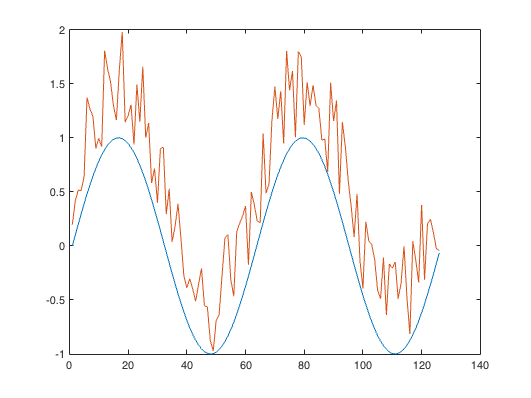

data1 =  sin(0:0.1:pi*4)+rand(1,size(kernel,2)); 
plot(data1)

We could calculate the dot product by doing the pointwise product and then summing across the products: 

for x = 1:size(kernel,2)
notthemostelegantway(x) = kernel(x) * data1(x); 
end
dotproduct4doubters = sum(notthemostelegantway)

dotproduct4doubters = 60.3415

We could calculate it more elegantly, using a bit of simple matrix algebra, because people who do math are prepared for recurring problems: 

dotproduct = kernel*data1'

dotproduct = 60.3415

disp(['dimensions of the kernel:  ', num2str(size(kernel))])

dimensions of the kernel:  1  126


disp(['dimensions of the data, flipped:  ', num2str(size(data1'))])

dimensions of the data, flipped:  126    1


Matrix multiplication implementation of the inner product

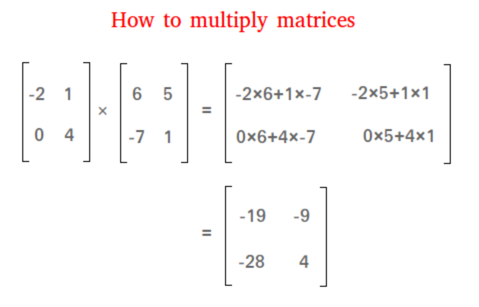

Matrices M1 and M2 are multiplied by multiplying the row elements of M1 with the column elements of M2, and the results added for each row/column pair. 

The sign for this is *

In Matlab, * is matrix multiplication and .* is elementwise individual multiplication without any addition. 

In this process, the inner dimensions get lost: 

The product of 2 M1 and M2 exists only if the number of columns of M1 (the second dimension) is equal to the number of rows of M2 (its first dimension).

a = rand(3,2)
size(a)
b = rand (2,3)
size(b)

The results has dimensions of rows of M1 and columns of M2 (again, the "inner" dimensions are lost, - but not the data of course)

c = a * b 
size(c)

more examples with random number matrices. 

what will the new dimensions be? 

rand(4,3) * rand(3,1)

rand(2,1) * rand(1,10)

rand(2,1) * rand(1,1)

[https://timeseriesreasoning.com/contents/deep-dive-into-variance-covariance-matrices/](https://timeseriesreasoning.com/contents/deep-dive-into-variance-covariance-matrices/)

inner product: 

matrix multiplication of two vectors of the same length, one is a row, one is a column vector

a1 = rand(1,4)
a2 = rand(4,1)

one more time, two vectors

a1 = [-1 1 -1 1] + 2
figure, bar(a1)
a2 = [-1 -1 1 1] + 2
figure, bar(a2)

The inner product between those two vectors

c = a1*a2'

so, the inner product is a measure of similarity between two vectors, it is high when they are similar, and low when they are not. In fact, the inner product is like an unscaled correlation coefficient. Let's try this

one more time, two vectors

a1 = [-1 1 -1 1]
figure, bar(a1)
a2 = [-1 .5 -1 1]
figure, bar(a2)

The inner product between those two vectors

c = a1*a2'